try 
d.unload
catch ERR
end 

EPANET Class is unloaded


fclose all;clear class;clear;clc;close all;
addpath(genpath(pwd));


### Choose network and uncertainty

% Network
inpname = 'Simple_Example2_mult.inp';
d = epanet(inpname);

EPANET version {20101} loaded (EMT version {dev2.2}).
Loading File "Simple_Example2_mult.inp"...
Input File "Simple_Example2_mult.inp" loaded sucessfuly.


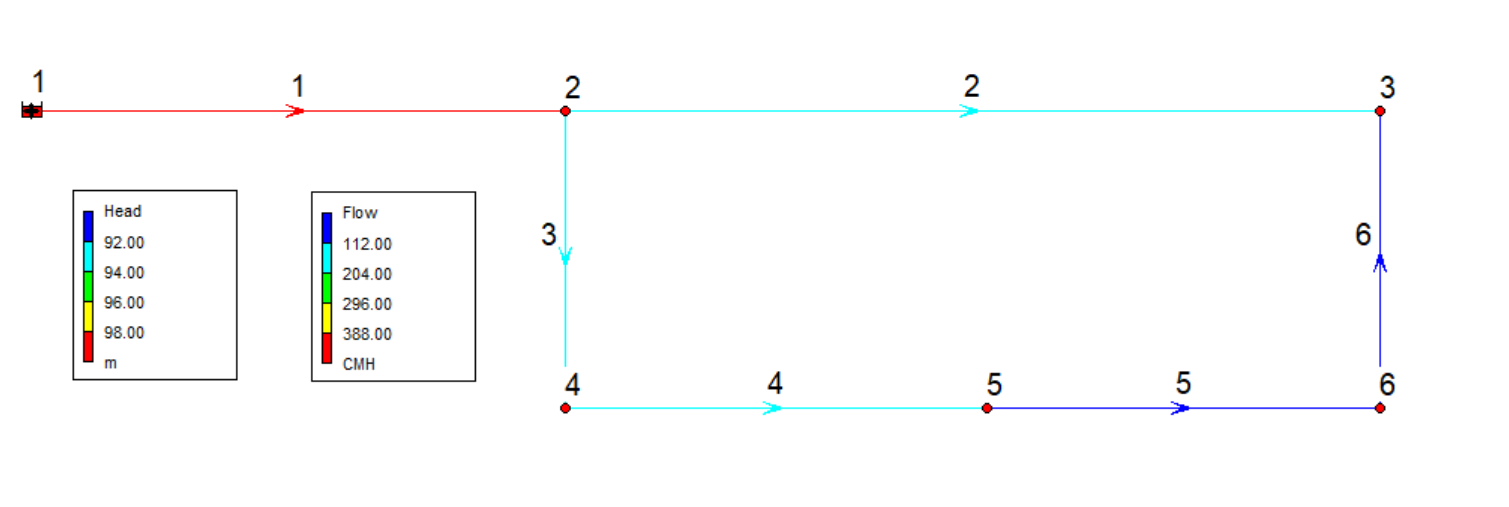

Define sensor nodes and input nodes:

% Sensor nodes
SensorID = '3'

SensorID = '3'

SourceID = '1' % Source node id

SourceID = '1'

Define simulation times:

% Times:
SimDays = 1;
SimTime = SimDays*24*3600;% Set simulation time
th=300;% 5-min hydraulic step
tq=300;% 5-min quality step
tstep=300;% 5-min reporting
m=SimTime/tq+1;% forecast for a day
time = 1:m; % time in hours
d.setTimeSimulationDuration(SimTime) 
d.setTimeHydraulicStep(th); 
d.setTimeQualityStep(tq); 
d.setTimeReportingStep(tstep); 
d.setTimePatternStep(tstep)


Setup quality simulation:

Nnodes = d.getNodeCount; % Get the number of nodes
sourceindex = d.getNodeIndex(SourceID); % Get source node's index
senNodind = double(d.getNodeIndex(SensorID)); %sensor nodes
d.setQualityType('Chlorine', 'mg/L', '') % Setup system to analyze for chlorine
zeroNodes=zeros(1,d.NodeCount); % make all initial concentrations 0 mg/L
d.setNodeInitialQuality(zeroNodes);

### **Create the impulse response matrix H using simulations:**

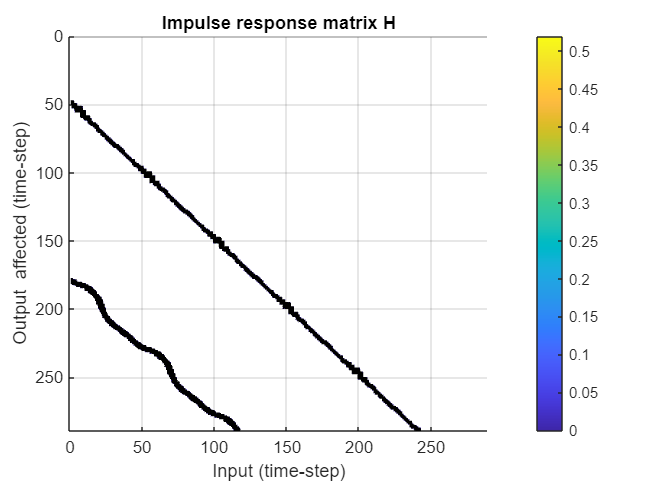

load H_multi_decay
% H = zeros(m,m);
% d.getComputedTimeSeries;
% for i = 1:m
%     PAT = zeros(1,m);
%     PAT(i) = 1;
%     patidx = d.addPattern('CL2PAT',PAT); % create the impulse responses
%     Q = d.getComputedQualityTimeSeries.NodeQuality;
%     H(:,i) = Q(:,senNodind);
% end
% PAT = U;% reset quality input
% patidx = d.addPattern('CL2PAT',PAT); 
% Q = d.getComputedQualityTimeSeries.NodeQuality;
% save('/saved_sim/H_multi_decay','H')

figure
[X,Y] = meshgrid(1:m,1:m);
surf(X,Y,H)
xlim([0 m])
ylim([0 m])
zlim([0.001 1])
view([0 -90.000])
xlabel('Input (time-step)')
ylabel('Output  affected (time-step)')
title('Impulse response matrix H')
colorbar

### Find impulse response matrix using the BUBA without uncertainty:

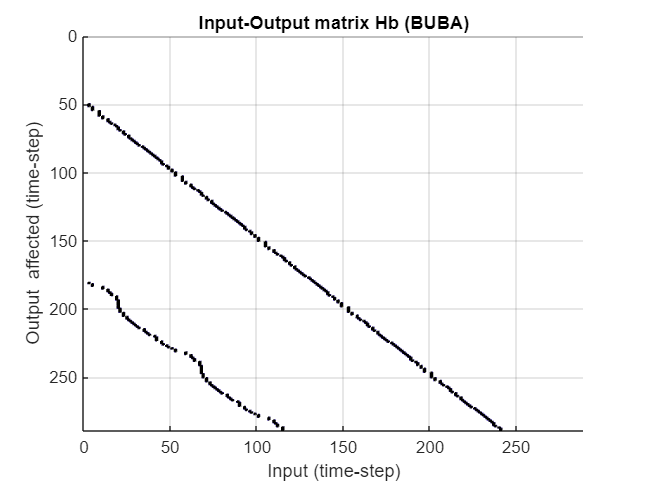

stateEstim = d.getComputedTimeSeries;
stateEstim.FlowUB = stateEstim.Flow;%flow_up;%
stateEstim.FlowLB = stateEstim.Flow;%flow_lo;%
Kdunc=0.0001; %decay rate uncertainty

Hb = BUBIM(d,SourceID,SensorID,stateEstim,Kdunc);
figure
[X,Y] = meshgrid(1:m,1:m);
surf(X,Y,Hb)
xlim([0 m])
ylim([0 m])
zlim([0.001 1])
view([0 -90.000])
xlabel('Input (time-step)')
ylabel('Output  affected (time-step)')
title('Input-Output matrix Hb (BUBA)')

### Estimate output without flow uncertainty:

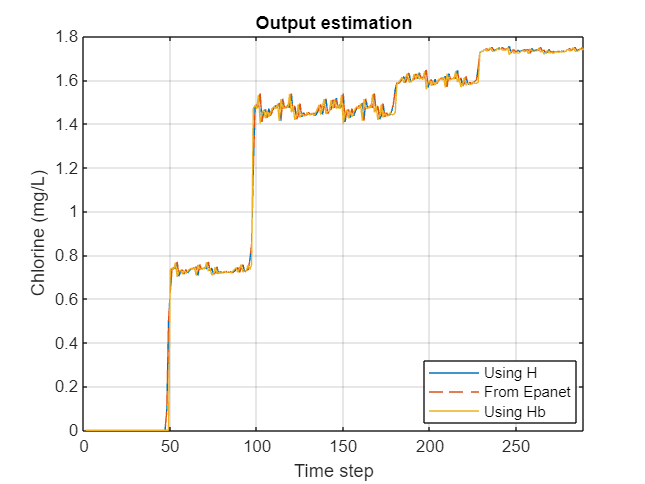

figure
U = ones(1,m); % setup arbitrary chlorine input pattern
U(50:end)=2;
Y=H*U'; %from impulse response
plot(Y)
grid on; hold all
patidx = d.addPattern('CL2PAT',U);
d.setNodeSourceType(sourceindex, 'SETPOINT');
d.setNodeSourcePatternIndex(sourceindex, patidx)
d.setNodeSourceQuality(sourceindex, 1)
d.getComputedTimeSeries;
Ytrue = d.getComputedQualityTimeSeries.NodeQuality; % from epanet
plot(Ytrue(:,senNodind),'--')
Yb=Hb*U'; %from BUBA
plot(Yb)
xlim([0 m]);
legend('Using H', 'From Epanet','Using Hb','Location',"best")
xlabel('Time step')
ylabel('Chlorine (mg/L)')
title('Output estimation')

### Predictive control when delay is certain **using quadratic optimization with constraints:**

Define output refernce signal:

r = 0.5*ones(m,1); % reference signal
r(1:100)=0; % allow dead period in the beginning

Calculate control input for a prediction horizon by formulating a quadratic optimization problem with constraints.

Note: Here we ignore the future responses vector $f$ (due to past inputs) and error $\hat{n}$

Itemp = [zeros(m,1) eye(m)]; 
Itemp(:,end)=[];
Itilda=eye(m)-Itemp; % with \Delta u penalization
% Itilda=eye(m); % uncomment for u penalization
l = 0.5; % weight on \Delta_u OR u penalization

G = 2*(Hb'*Hb + l*Itilda);
b = 2*(-r)'*Hb;
Aeq=[]; beq=[];
Aineq=-Hb;
bineq=-r; % output lower bound constraint
lb=zeros(m,1); %input lower bound
ub=ones(m,1); %input upper bound

Umpc = quadprog(G,b,Aineq,bineq,Aeq,beq,lb,ub); % quadratic optimization


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Plot control input and resulting output:

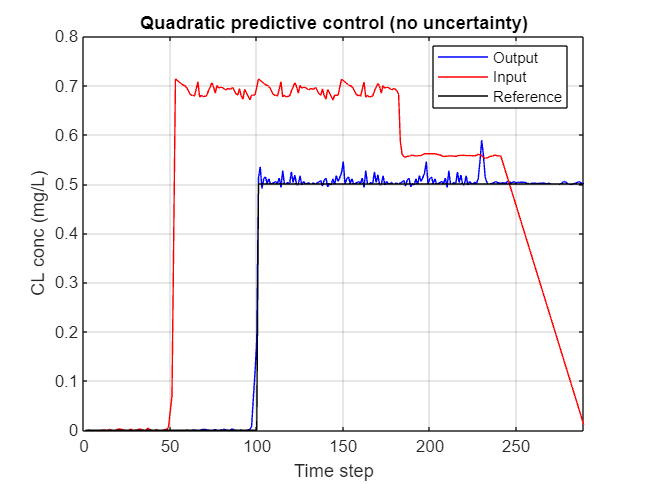

figure
plot(H*Umpc,'b')
grid on; hold all
plot(Umpc,'r')
plot(r,'k')
xlim([0 m]);
xlabel('Time step');ylabel('CL conc (mg/L)')
legend('Output','Input','Reference','Location',"best")
title('Quadratic predictive control (no uncertainty)')

### Run multiple scenarios to simulate the flow uncertainty

Calculate flow upper and lower bound for each pipe and the impulse response matrices 'HALL' from all scenarios.

load HALL_multi3
qunc=0.1;
dem_scen=50;
bdem = d.getNodeBaseDemands{1};
% flow_up=-inf(1,d.getLinkCount);
% flow_lo= inf(1,d.getLinkCount);
% % figure; hold all;
% HALL=[];
% for dem=1:dem_scen
%     dem
%     bdemrnd=bdem + qunc*(1-2*rand(size(bdem))).*bdem; % demand uncertainty
%     d.setNodeBaseDemands(bdemrnd);
%     flow=d.getComputedHydraulicTimeSeries.Flow;
%     flow_up=max(flow,flow_up);
%     flow_lo=min(flow,flow_lo);
% %     plot(time,flow, 'Color', [0.5 0.5 0.5])
%     for i = 1:m
%         clc
%         if mod(i,50)==0
%             i
%         end
%         PAT = zeros(1,m);
%         PAT(i) = 1;
%         patidx = d.addPattern('CL2PAT',PAT); % create the impulse responses
%         Q = d.getComputedQualityTimeSeries.NodeQuality;
%         H(:,i) = Q(:,senNodind);
%     end
%     HALL{dem}=H;
% end
% save('HALL_multi3','HALL','flow_lo','flow_up')
% d.setNodeBaseDemands(bdem) %reset base demands
% PAT = U; % reset quality input
% patidx = d.addPattern('CL2PAT',PAT); 
% d.getComputedTimeSeries;

Plot flow bounds:

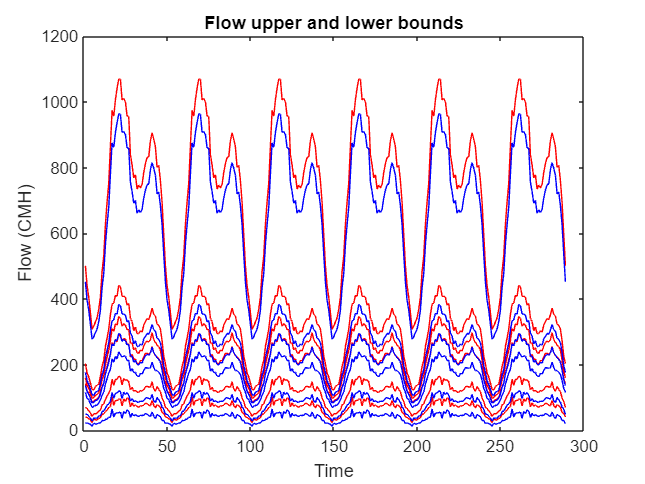

figure
plot(time,flow_up,'r')
hold all
plot(time,flow_lo,'b')
xlabel('Time'); ylabel('Flow (CMH)')
title('Flow upper and lower bounds')

### Combine and plot EPANET uncertain impulse response matrix created using all simulated scenarios:

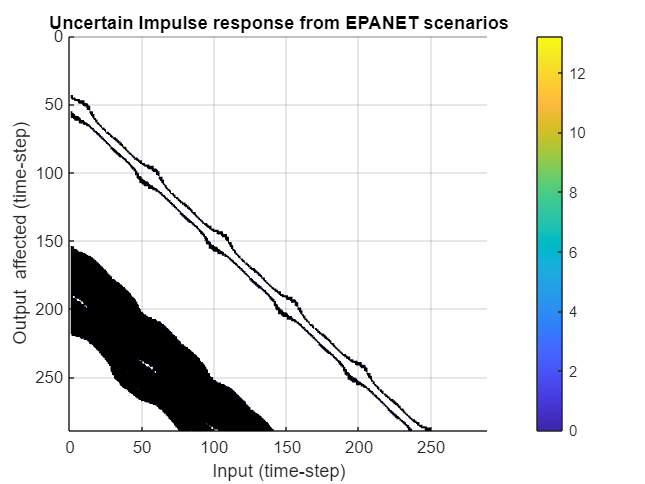

Hall=zeros(size(HALL{1}));
for i =1:dem_scen
    Hall = Hall+HALL{i};
end
figure
[X,Y] = meshgrid(1:m,1:m); surf(X,Y,Hall)
xlim([0 m]);ylim([0 m]);zlim([0.001 1]);view([0 -90.000])
xlabel('Input (time-step)')
ylabel('Output  affected (time-step)')
title('Uncertain Impulse response from EPANET scenarios')
colorbar

**Number of paths** is the number of input time-steps that can **simultaneously affect the output**. The other input time-steps are uncertainty.

### Backtrack to find all inputs possibly affecting the output using the BUBA:

stateEstim = d.getComputedTimeSeries;

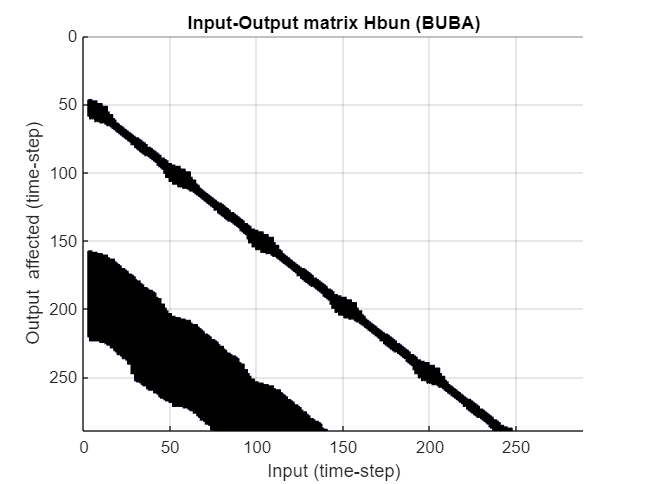

stateEstim.FlowUB = flow_up;
stateEstim.FlowLB = flow_lo; % this may not contain all flow scenarios
Kdunc=0.001; %decay rate uncertainty

% load Hbun
Hbun = BUBIM(d,SourceID,SensorID,stateEstim,Kdunc);
% save('Hbun','Hbun')

figure
[X,Y] = meshgrid(1:m,1:m); surf(X,Y,Hbun); 
xlim([0 m]); ylim([0 m]); zlim([0.001 1]); view([0 -90.000]);
xlabel('Input (time-step)')
ylabel('Output  affected (time-step)')
title('Input-Output matrix Hbun (BUBA)')

Note: The backtracking approach here finds only one input affecting the output due to known flows. It actually chooses the most probable time-step.

In contrast, the impulse response matrix approach may divide the effect to multiple inputs. All rows add up to one, both for H and for Hb (BUBA)

### Create two separate impulse responses matrices, one for each path:

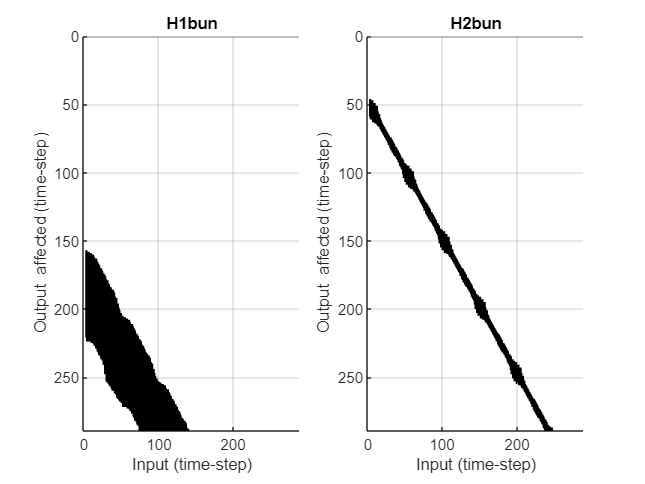

H1bun = zeros(m,m);
H2bun = zeros(m,m);
for x=1:289
    for y=1:289
        if x>y+100
            H1bun(x,y)=Hbun(x,y);
        else
            H2bun(x,y)=Hbun(x,y);
        end
    end
end
figure
subplot(1,2,1)
[X,Y] = meshgrid(1:m,1:m); surf(X,Y,H1bun)
xlim([0 m]);ylim([0 m]);zlim([0.001 1]);view([0 -90.000])
xlabel('Input (time-step)')
ylabel('Output  affected (time-step)')
title('H1bun')
subplot(1,2,2)
[X,Y] = meshgrid(1:m,1:m); surf(X,Y,H2bun)
xlim([0 m]);ylim([0 m]);zlim([0.001 1]);view([0 -90.000])
xlabel('Input (time-step)')
ylabel('Output  affected (time-step)')
title('H2bun')

### Create new impulse response matrix by averaging the uncertainty:

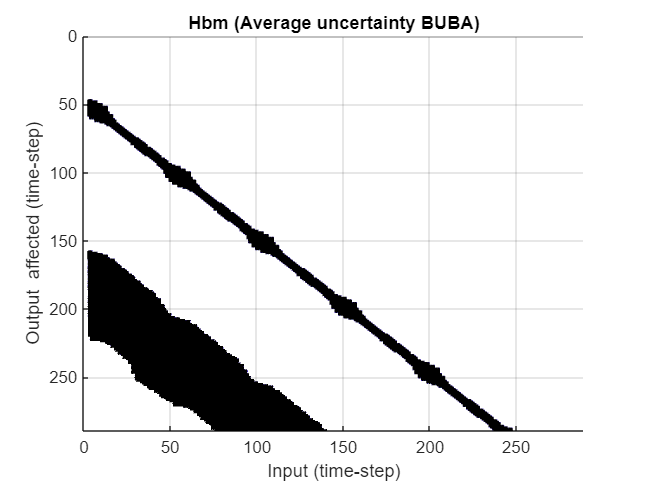

% Find path 1 mean uncertainty impulse response H1bm:
H1bm=zeros(size(H1bun));
for i=1:m
    n=sum(double(H1bun(i,:)>0));
    if n~=0
        H1bm(i,:)=H1bun(i,:)/n;
    end
end
% Find path 1 mean uncertainty impulse response H2bm:
H2bm=zeros(size(H2bun));
for i=1:m
    n=sum(double(H2bun(i,:)>0));
    if n~=0
        H2bm(i,:)=H2bun(i,:)/n;
    end
end
% Find mean uncertainty impulse response Hbm:
Hbm=(H1bm+H2bm);

figure
[X,Y] = meshgrid(1:m,1:m); surf(X,Y,Hbm); 
xlim([0 m]); ylim([0 m]); zlim([0.001 1]); view([0 -90.000]);
xlabel('Input (time-step)')
ylabel('Output  affected (time-step)')
title('Hbm (Average uncertainty BUBA)')

### Quadratic predictive control using Hbm:

Itemp = [zeros(m,1) eye(m)]; 
Itemp(:,end)=[];
Itilda=eye(m)-Itemp; % with \Delta u penalization
% Itilda=eye(m); % uncomment for u penalization
l = 20; % weight on \Delta_u OR u penalization

G = 2*(Hbm'*Hbm + l*Itilda);
b = 2*(-r)'*Hbm;
Aeq=[]; beq=[];
Aineq=-Hb;
bineq=-r; %output lower bound constraint
lb=zeros(m,1); %input lower bound
ub=1*ones(m,1); %input upper bound

UmpcUN = quadprog(G,b,Aineq,bineq,Aeq,beq,lb,ub); % quadratic optimization


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


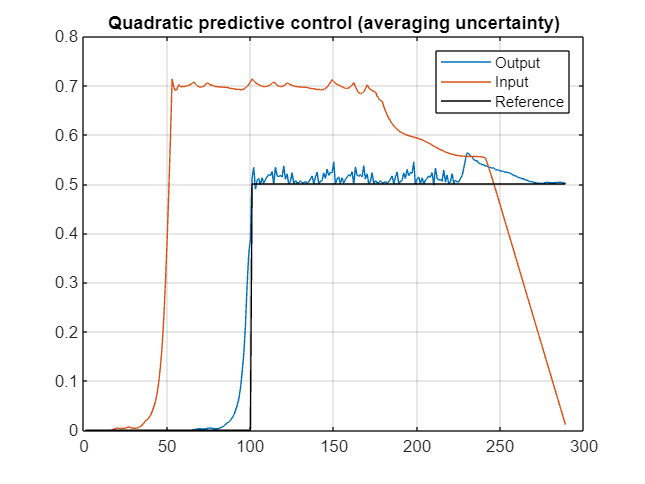

figure
plot(H*UmpcUN)
grid on; hold all
plot(UmpcUN)
plot(r,'k')
legend('Output','Input','Reference')
title('Quadratic predictive control (averaging uncertainty)')

### Calculate input using the uncertain impulse response matrices:


$$\arg\min_U ||\tilde{Y}-R||_2^2+||\Delta U_k||_2^2$$



$$subject\,to:$$


- $\tilde{Y}=\tilde{H}U$, nominal model for tracking

- $\underline{U}\le U \le \overline{U}$, control input constraints

- $\underline{y_k}\le y_k \le \overline{y}_k , \, \forall k$, output constraints

- $y_k=h_{kj} \,u_j,\,\, \forall j
$, mulitple possible outputs

Set parameter Username
Academic license - for non-commercial use only - expires 2024-11-23
Gurobi Optimizer version 9.5.2 build v9.5.2rc0 (win64)
Thread count: 6 physical cores, 12 logical processors, using up to 12 threads
Optimize a model with 9376 rows, 867 columns and 18752 nonzeros
Model fingerprint: 0xa6bc155e
Model has 2499 quadratic objective terms
Coefficient statistics:
  Matrix range     [1e-01, 1e+00]
  Objective range  [5e-02, 1e+00]
  QObjective range [2e-09, 2e+00]
  Bounds range     [1e-01, 1e+00]
  RHS range        [1e-04, 5e-01]
Presolve removed 1309 rows and 446 columns
Presolve time: 0.01s
Presolved: 8067 rows, 421 columns, 16134 nonzeros
Presolved model has 2499 quadratic objective terms
Ordering time: 0.20s
Ordering time: 0.40s

Barrier statistics:
 Dense cols : 95
 Free vars  : 287
 AA' NZ     : 3.245e+05
 Factor NZ  : 1.962e+06 (roughly 20 MB of memory)
 Factor Ops : 1.252e+09 (less than 1 second per iteration)
 Threads    : 6

                  Objective       

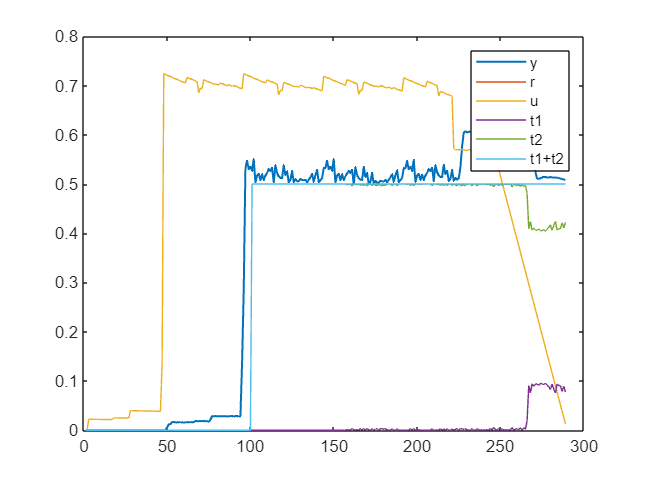

[Ugurobi] = unc_control5(H,H1bun,H2bun,m,r); % two paths

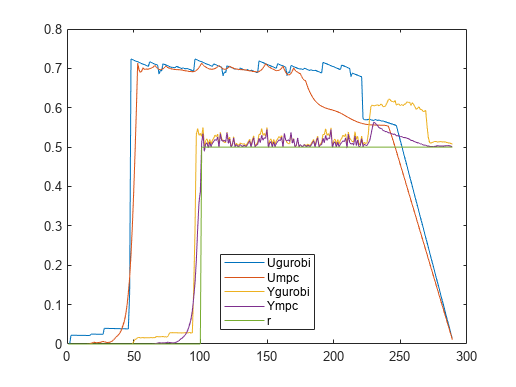

figure
plot(Ugurobi)
hold all
plot(UmpcUN)
plot((H)*Ugurobi)
plot((H)*UmpcUN)
plot(r)
legend('Ugurobi','Umpc','Ygurobi','Ympc','r','Location','Best')

### Compare input calculated using certain and uncertain models:

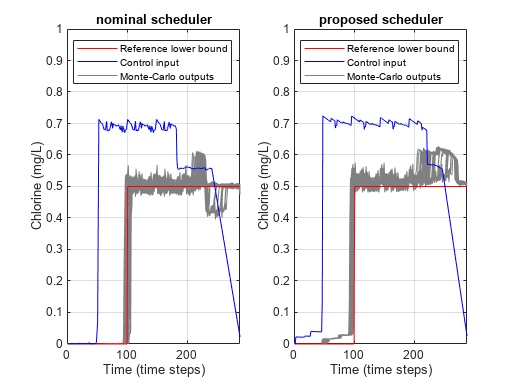

figure; 
subplot(1,2,1)
plot(r,'r')
hold on
plot(Umpc,'b')
plot(time,HALL{1}*Umpc,'Color',[0.5 0.5 0.5])
grid on; xlabel('Time (time steps)'); ylabel('Chlorine (mg/L)')
title('nominal scheduler')
ylim([0 1]);xlim([0 288])
legend('Reference lower bound','Control input','Monte-Carlo outputs','AutoUpdate','off')

subplot(1,2,2)
plot(r,'r')
hold on
plot(Ugurobi,'b')
ygur=HALL{1}*Ugurobi;
plot(time,ygur,'Color',[0.5 0.5 0.5])
grid on; xlabel('Time (time steps)'); ylabel('Chlorine (mg/L)')
title('proposed scheduler')
ylim([0 1]);xlim([0 288])
legend('Reference lower bound','Control input','Monte-Carlo outputs','AutoUpdate','off')

for i=1:length(HALL)
    subplot(1,2,1) % normal input
    hold on;
    plot(time,HALL{i}*Umpc,'Color',[0.5 0.5 0.5])
    subplot(1,2,2) % normal input
    hold on;
    ygur=HALL{i}*Ugurobi; 
    plot(time,ygur,'Color',[0.5 0.5 0.5])
end

subplot(1,2,1)
plot(r,'r','LineWidth',1)
hold on
plot(Umpc,'b','LineWidth',1)

subplot(1,2,2)
plot(r,'r','LineWidth',1)
hold on
plot(Ugurobi,'b','LineWidth',1)